disp('SPHERICAL_MODERN')

SPHERICAL_MODERN


syms a1 a2 a3

a1 = 2;
a2 = 2;
a3 = 2;

H0_1 = Link([0,a1,0,pi/2,0,0]);
H0_1.qlim = pi/180*[-90 90];

H1_2 = Link([pi/2,0,a2,pi/2,0]);
H1_2.qlim = pi/180*[-90 90];

H2_3 = Link([0,0,0,0,1,a3]);
H2_3.qlim = [0 3];

SPHERICAL_MODERN = SerialLink([H0_1 H1_2 H2_3], 'name', 'SPHERICAL_MODERN')

 
SPHERICAL_MODERN = 
 
SPHERICAL_MODERN:: 3 axis, RRP, stdDH, slowRNE                   
+---+-----------+-----------+-----------+-----------+-----------+
| j |     theta |         d |         a |     alpha |    offset |
+---+-----------+-----------+-----------+-----------+-----------+
|  1|         q1|          2|          0|     1.5708|          0|
|  2|         q2|          0|          2|     1.5708|          0|
|  3|          0|         q3|          0|          0|          2|
+---+-----------+-----------+-----------+-----------+-----------+
 


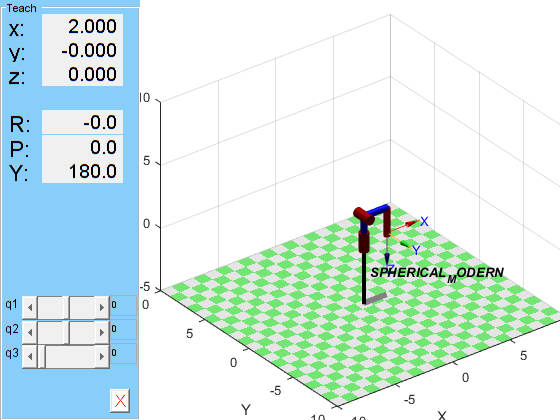

SPHERICAL_MODERN.plot([0 0 0 ], 'workspace', [-10 10 -10 10 -5 10])
SPHERICAL_MODERN.teach